## DFT/FFT demo - comparing DFT and dot product

This demo illustrates the fundamentals of Discrete Fourier Transform (DFT) often called or implemented as FFT. DFT is the most widely used method for obtaining a frequency spectrum (with frequency on the x-axis and amplitude/power/magnituve on the y-axis) of a neural time series. It runs best under Matlab 2021 or later versions.

We start by making a discrete time vector, at which the signal will be sampled. 

clear
time = 0.001:0.001:1; % one second of discrete time, sampled at 1000 Hz

now, we make a time series of Brownian noise (biorealistic) time series not unlike EEG/LFP, representing one trial of neural mass data

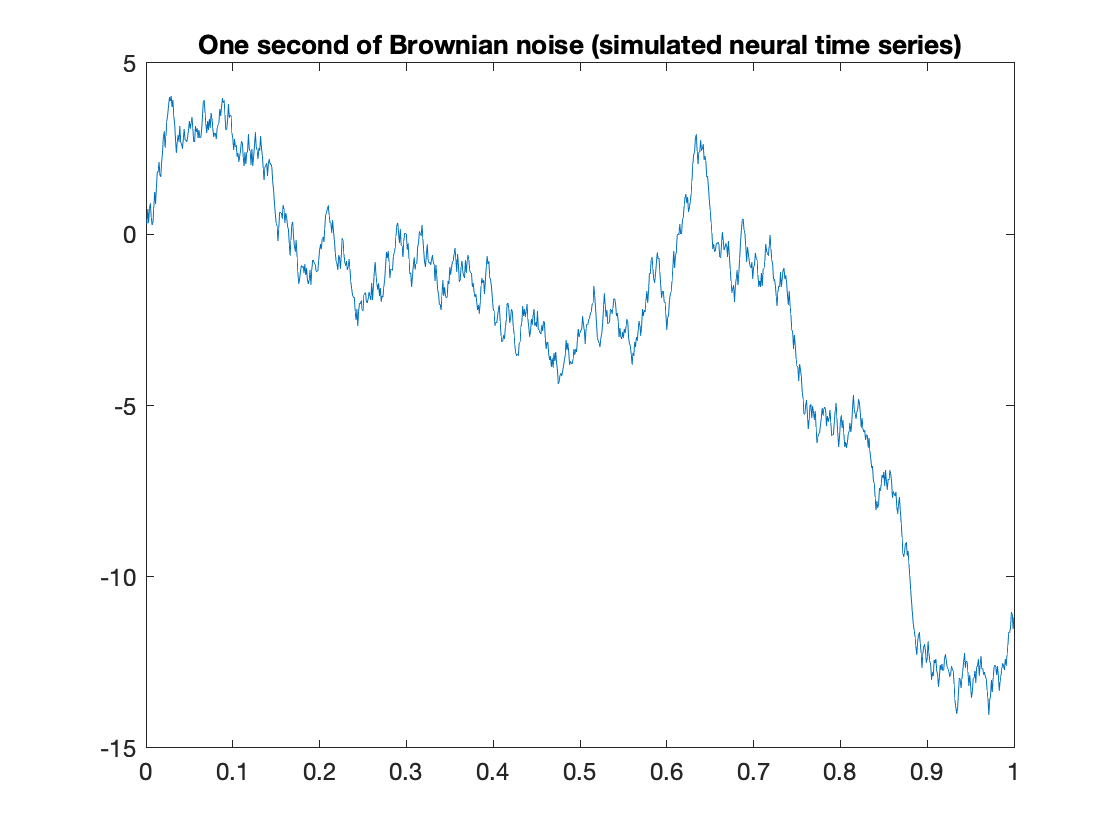

temp1 = rand(size(time))-.5; % zero-center the white noise, because we use cumulative sum later
brownsig = cumsum(temp1);  % Brownian noise is the cumulative sum of white noise
figure
plot(time, brownsig),title('One second of Brownian noise (simulated neural time series)') 

Now we make 3 simple signals, to be added to the brownian noise.

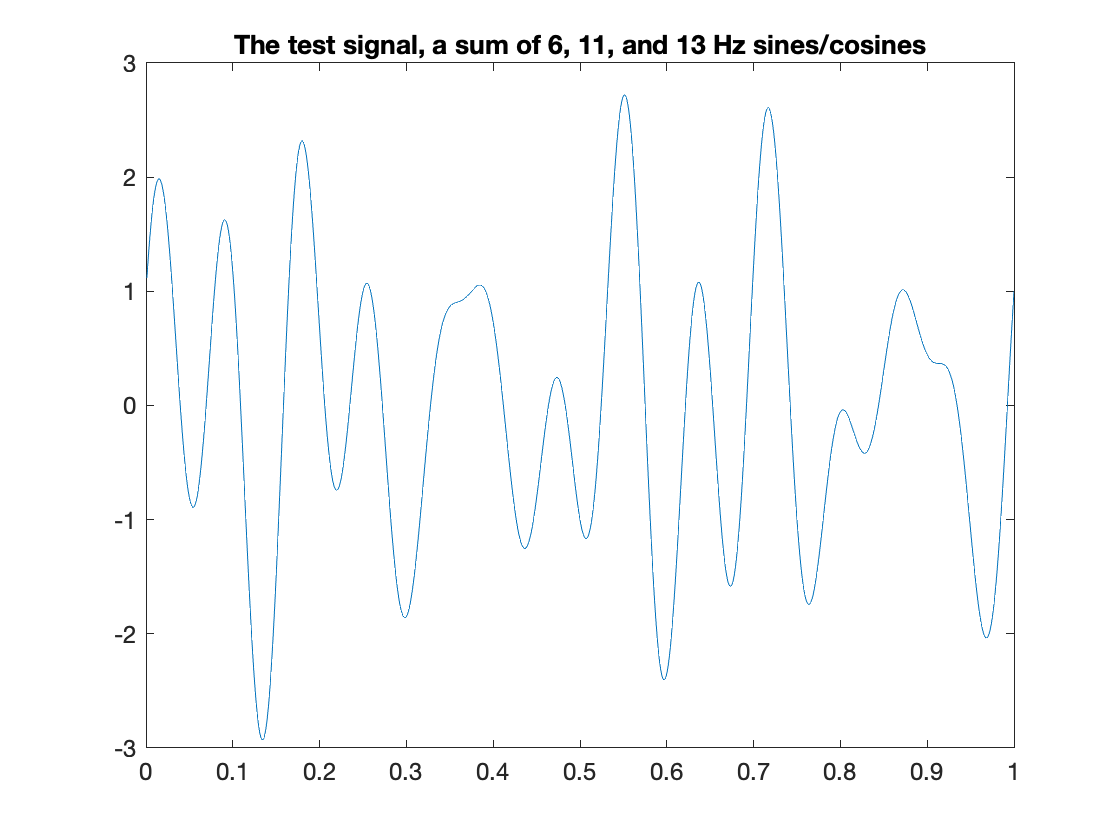

Sin6Hz = sin(2*pi*time*6); % a 6 Hz sine wave
Cos11Hz = cos(2*pi*time*11); % a 11 Hz cosine wave
Sin13Hz = sin(2*pi*time*13); % a 13 Hz sine wave

sumsig = Sin6Hz + Cos11Hz + Sin13Hz; 
figure
plot(time, sumsig), title('The test signal, a sum of 6, 11, and 13 Hz sines/cosines') 

The sum of the three test signals, two sinoids, one cosinoid is now added to the Brownian noise

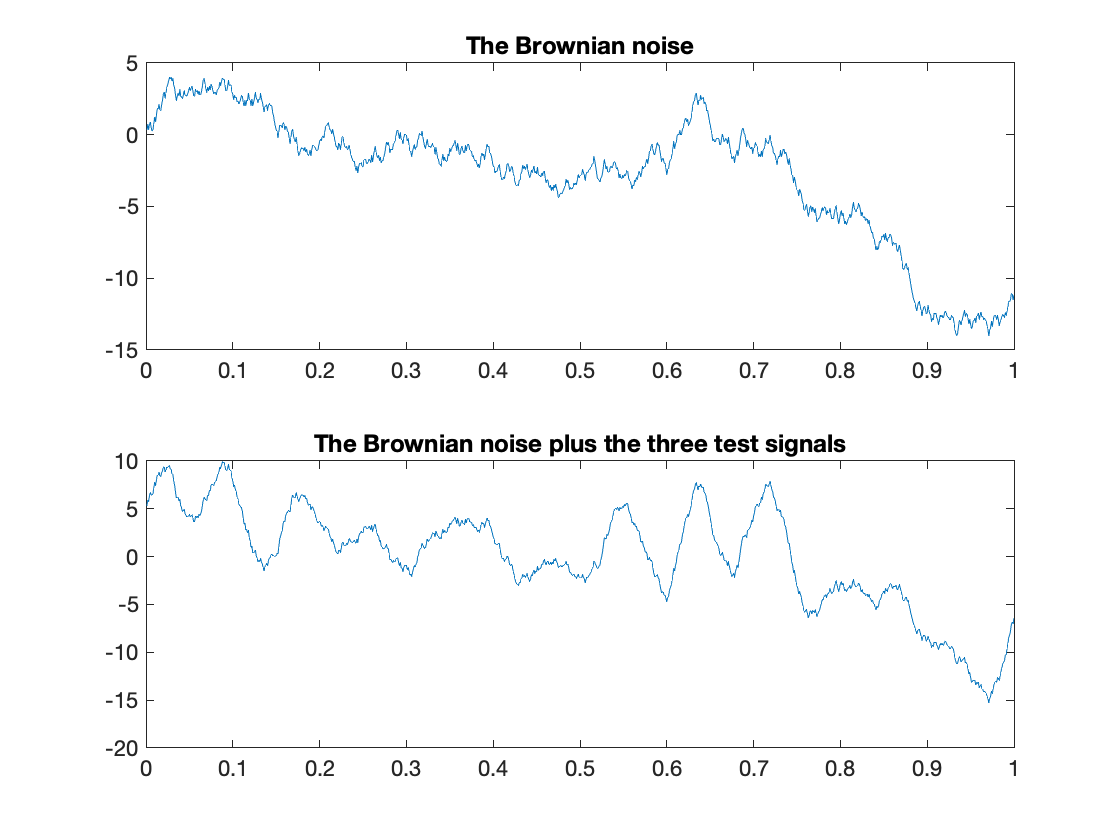

testsig1  = brownsig-mean(brownsig); % zero-centered Brownian noise
testsig = testsig1 + sumsig.*2; % multiply sum of sine/cosine signals by 2 to make it more prominent
figure
subplot(2,1,1), plot(time, brownsig), title('The Brownian noise') % the real part
subplot(2,1,2), plot(time, testsig), title('The Brownian noise plus the three test signals') 

Now, we compute the Discrete Fourier Transform, resulting in a complex spectrum with real (cosine-base) and imaginary (sine-base) components. In most programming environments, this is just one line of code, and yields complex numbers, corresponding to the fit of sine and cosine templates for each frequency, with the data. More about this below. 

complexspectrum = fft(testsig);

We have a 1-sec segment, which means the frequency resolution is 1 Hz; sampled at 1000 Hz, the frequency axis goes from 0 Hz to 500 Hz (half the sample rate, called the Nyquist Frequency). See Matt Carrick's excellent explanation here: [https://www.wavewalkerdsp.com/2022/03/16/dft-frequency-resolution-explained/](https://www.wavewalkerdsp.com/2022/03/16/dft-frequency-resolution-explained/) 

faxis = 0:500; 

Plot the resulting spectra, one for the real part, one for the imaginary part, and the (combined) amplitude spectrum. Here, we plot only frequencies between 0 and 30 Hz for speed and ease. 

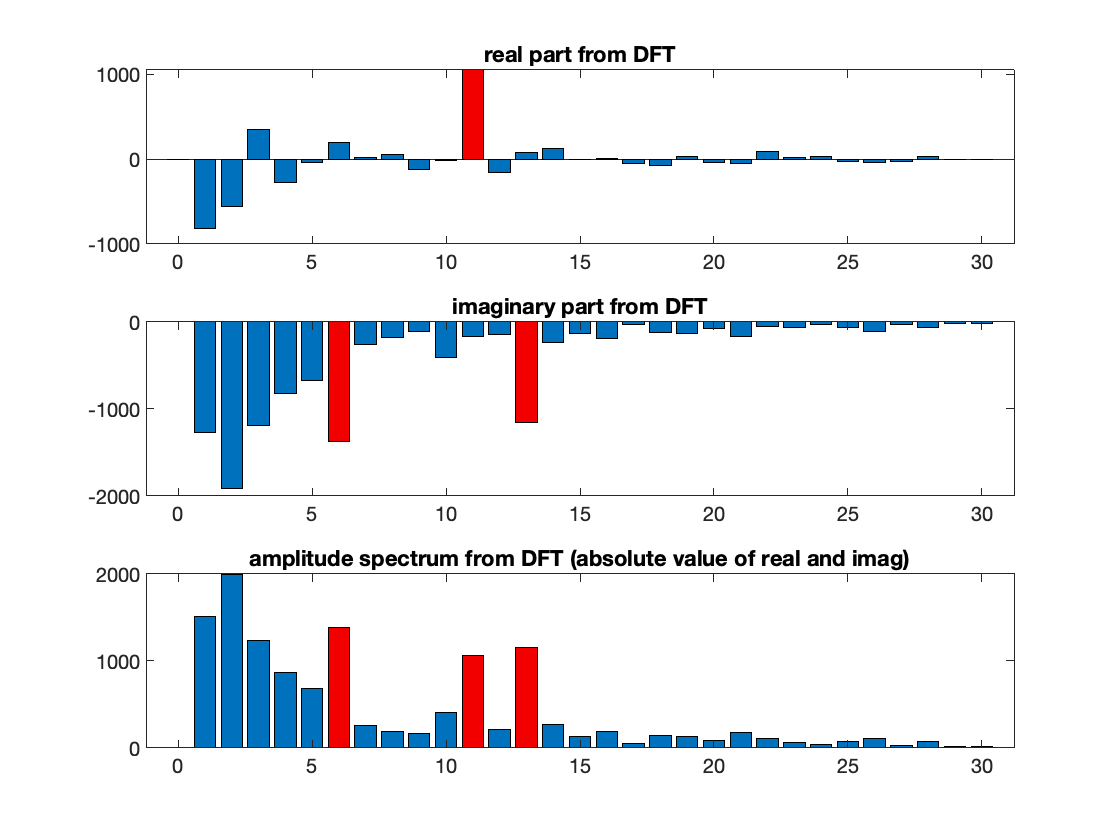

figure
subplot(3,1,1), b1 = bar(faxis(1:31), real(complexspectrum(1:31))); title('real part from DFT') % the real part
b1.FaceColor = 'flat'; b1.CData(12,:) = [.95 0 0]; % this is just to make the seed frequencies red

subplot(3,1,2), b2 = bar(faxis(1:31), imag(complexspectrum(1:31))); title('imaginary part from DFT') % the imaginary part
b2.FaceColor = 'flat'; b2.CData([7 14],:) = [.95 0 0; .95 0 0]; % this is just to make the seed frequencies red

subplot(3,1,3), b3 = bar(faxis(1:31), abs(complexspectrum(1:31))); title('amplitude spectrum from DFT (absolute value of real and imag)')% the absolute value
b3.FaceColor = 'flat'; b3.CData([7 12 14],:) = [.95 0 0; .95 0 0; .95 0 0]; % this is just to make the seed frequencies red

Now, let's examine the inner workings of the DFT: Instead of computing the DFT, we compute by hand (OK not really by hand) the *dot product* of each ***cosine*** template (for each frequency) with the data.  [https://en.wikipedia.org/wiki/Dot_product.](https://en.wikipedia.org/wiki/Dot_product.) This dot product should look like the real part (the cosine component) of the DFT. The dot product can be thought of as a correlation between a template and the data. It has a greater value when the data happen to look like the template (here, sine and cosine functions at different frequencies) and a lower value when template and data are differentlin time course. We highlight the frequency of the cosine wave we put into the Brownian noise test signal in **red**.

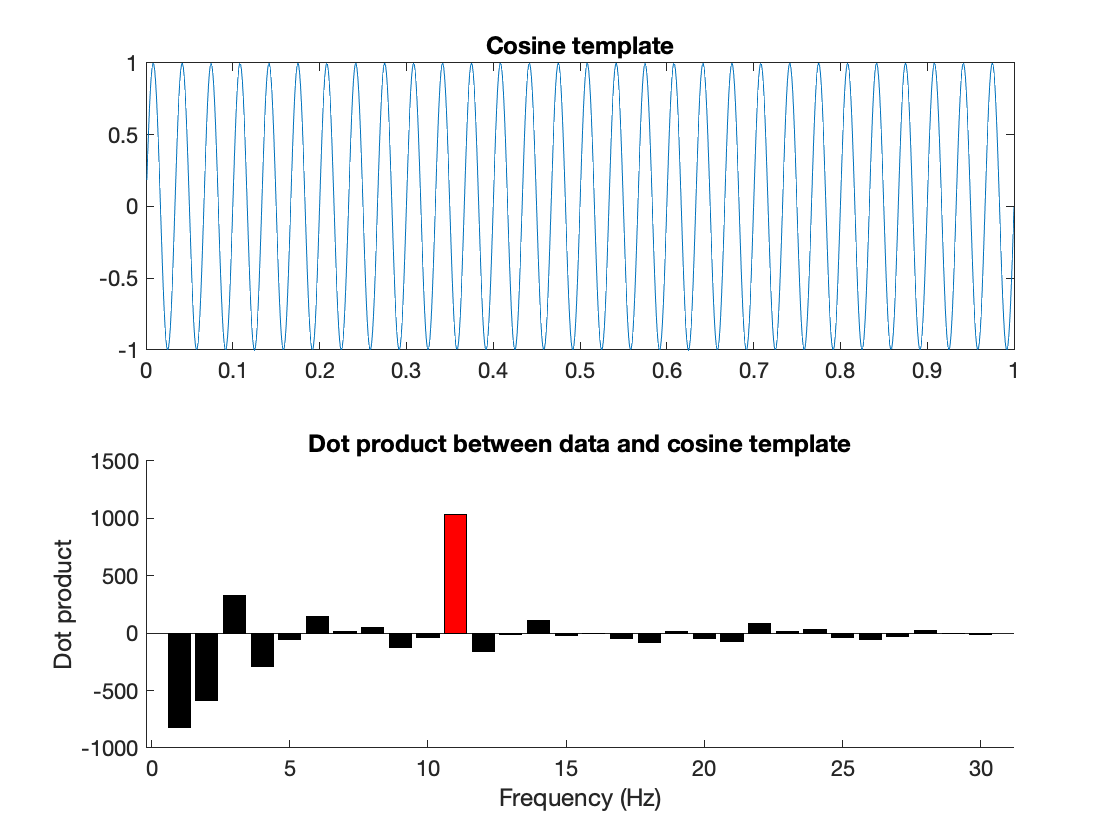

figure
for frequency = 1:30 % we only consder integer frequencies because then we can fit complete cycles of templates in the 1-sec segment. 
    cosdot(frequency) = testsig*cos(time*2*pi*frequency)'; 
    subplot(2,1,1), plot(time, sin(time*2*pi*frequency)), title('Cosine template')
    subplot(2,1,2), hold on, bar(frequency,cosdot(frequency), 'k'), if frequency==11, bar(frequency,cosdot(frequency), 'r'), end
    pause(1)
    title('Dot product between data and cosine template')
    xlabel('Frequency (Hz)')
    ylabel('Dot product')
end

Now we do this again, but this time computing the dot product of each ***sine*** wave template with the data. Note that the sign is opposite to the built-in DFT algorithm because of a Matlab convention. [https://www.mathworks.com/help/signal/ug/discrete-fourier-transform.html](https://www.mathworks.com/help/signal/ug/discrete-fourier-transform.html) 

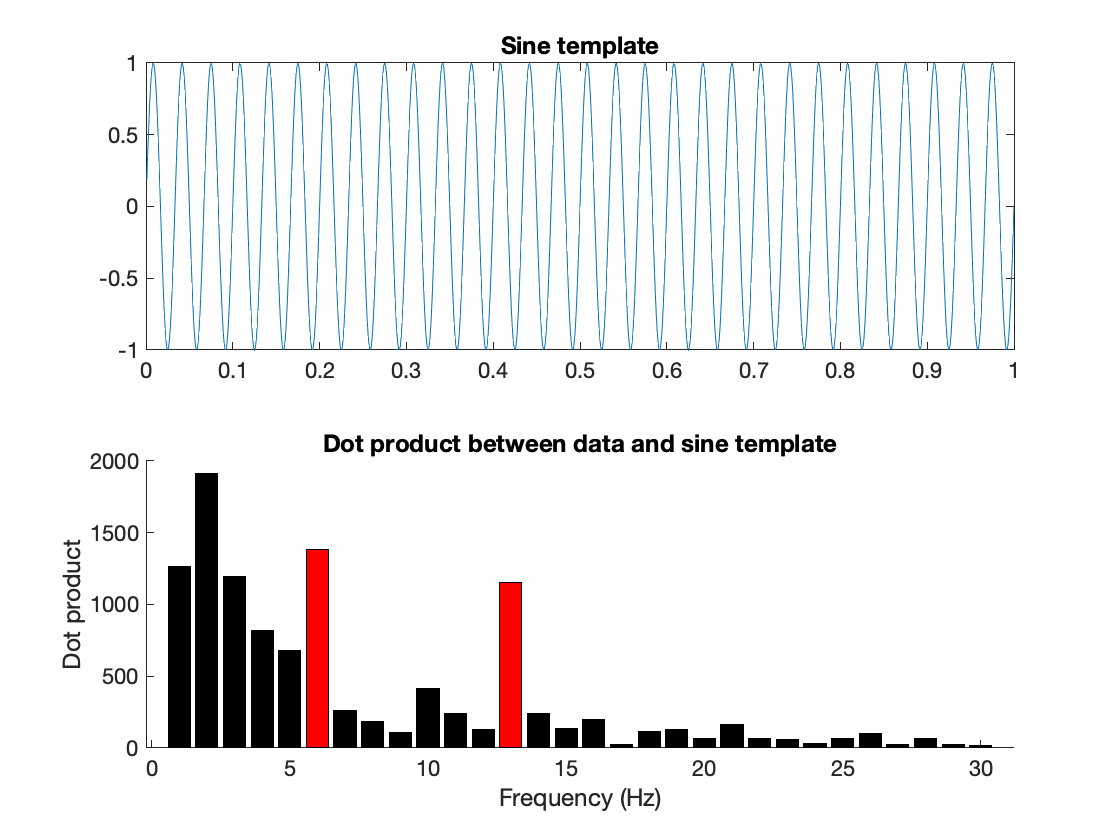

figure
for frequency = 1:30
    sindot(frequency) = testsig*sin(time*2*pi*frequency)'; 
    subplot(2,1,1), plot(time, sin(time*2*pi*frequency)), title('Sine template')
    subplot(2,1,2), hold on, bar(frequency,sindot(frequency), 'k'), if ismember(frequency, [6 13]), bar(frequency,sindot(frequency), 'r'), end
    pause(1)
    title('Dot product between data and sine template')
    xlabel('Frequency (Hz)')
    ylabel('Dot product')
end

Just like for the built-in DFT algorith,m we now calculate the amplitude spectrum by taking the modulus (absolute value) of the sine and cosine dotproducts. The absolute value for each frequency is simply the square root of the sum of the squares of the cosine dot product and sine dot products. Note that the resulting spectrum is very similar to the built-in DFT (FFT) function that matlab uses. Small differences are owed to slight difference in implementation in the buil-in algorithm. This concludes this demo. The goal is for you now have a better intuition of the inner workings of DFT/FFT algorithms applied, as they can be thought of as a frequency-wise application of sine and cosine filters to the data. There are a few more interesting aspects, including how the length (duration) of the time segment affects the DFT. There is a demo on that in this collection (introto_DFTuncertainty.mlx). Check it out. 

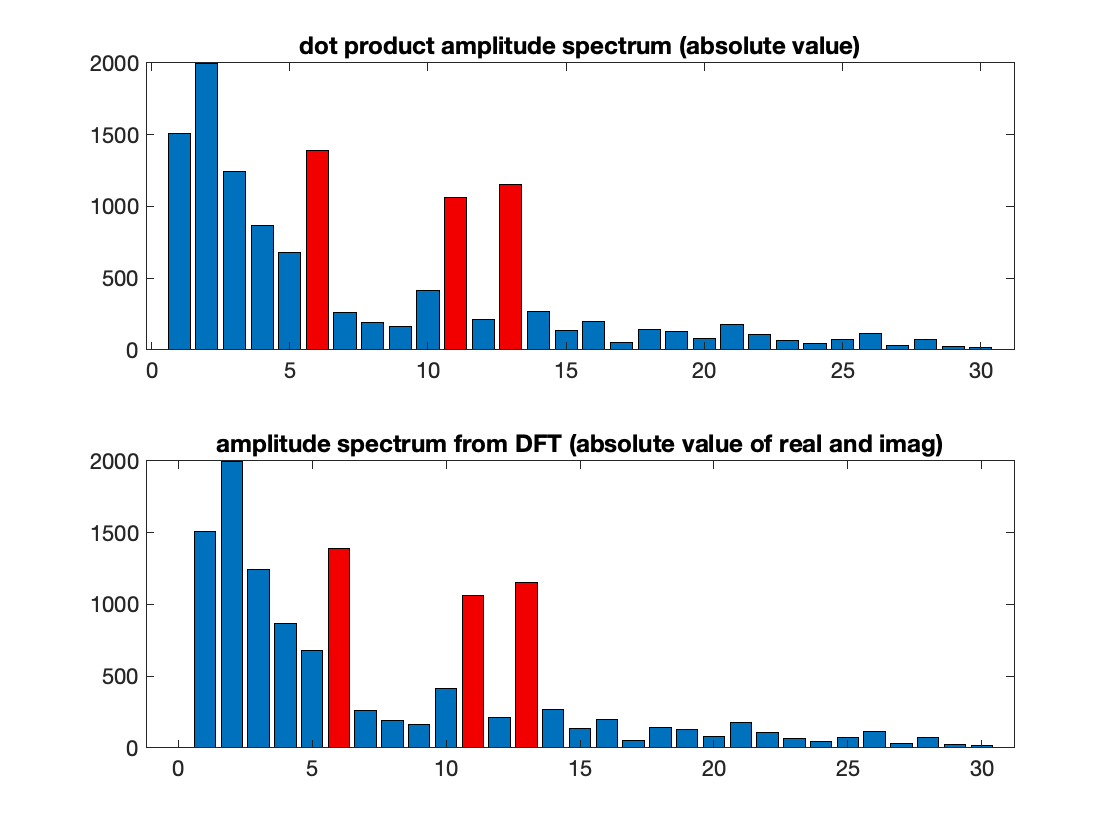

dotprodspec  = cosdot + 1i*sindot; 
figure
subplot(2,1,1),b4 = bar(1:30, abs(dotprodspec)); title('dot product amplitude spectrum (absolute value)')% the absolute value
b4.FaceColor = 'flat'; b4.CData([6 11 13],:) = [.95 0 0; .95 0 0; .95 0 0]; % this is just to make the seed frequencies red

subplot(2,1,2), b5 = bar(faxis(1:31), abs(complexspectrum(1:31))); title('amplitude spectrum from DFT (absolute value of real and imag)')% the absolute value
b5.FaceColor = 'flat'; b5.CData([7 12 14],:) = [.95 0 0; .95 0 0; .95 0 0]; % this is just to make the seed frequencies red